## 1

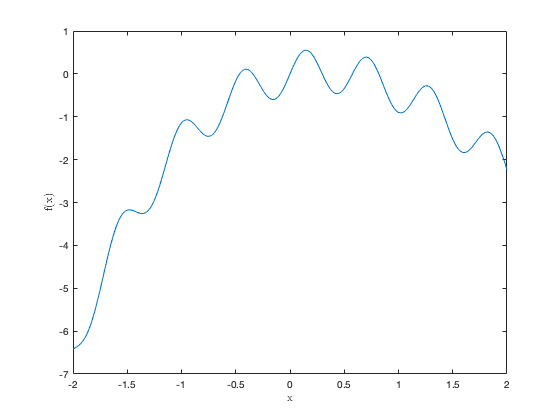

syms x
f = sin(6 * x) * cos(5 * x) - x^2 * exp(-x / 5);
f = matlabFunction(f);

a = -2;         % left bound of interval
b = 2;          % right bound of interval
h = 0.001;      % step size for plotting

xx = a:h:b;
yy = f(xx);

plot(xx, yy)

xlabel('x', 'Interpreter', 'latex');
ylabel('f(x)', 'Interpreter', 'latex');

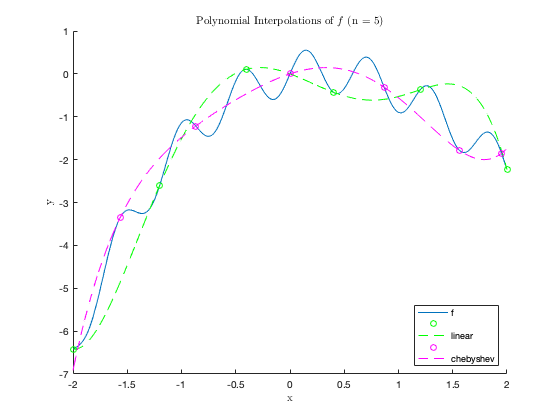

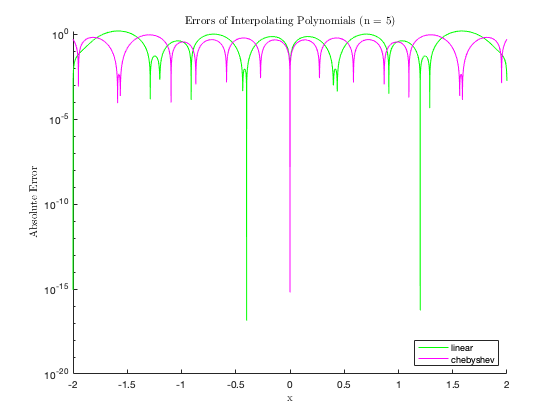

max linear error: 1.52225


max chebyshev error: 0.90791

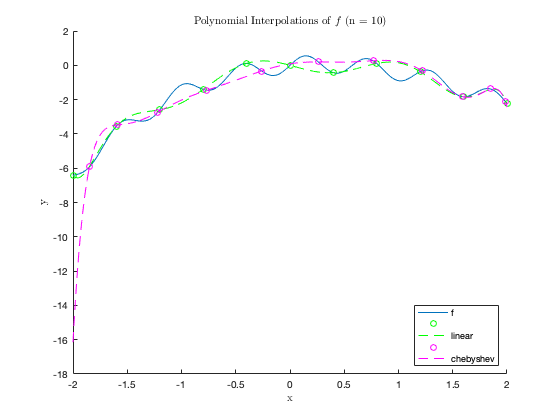

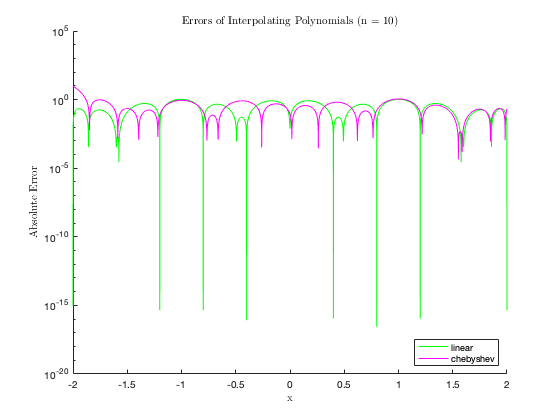

max linear error: 1.04586


max chebyshev error: 9.72581

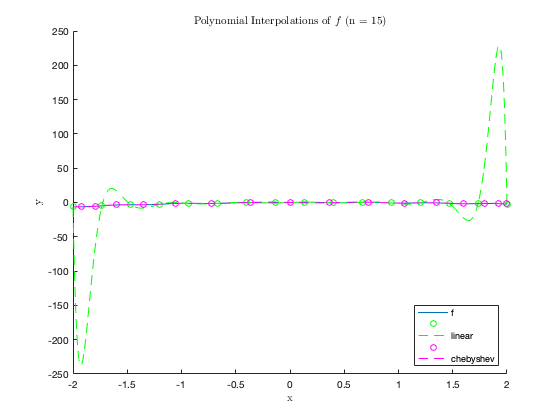

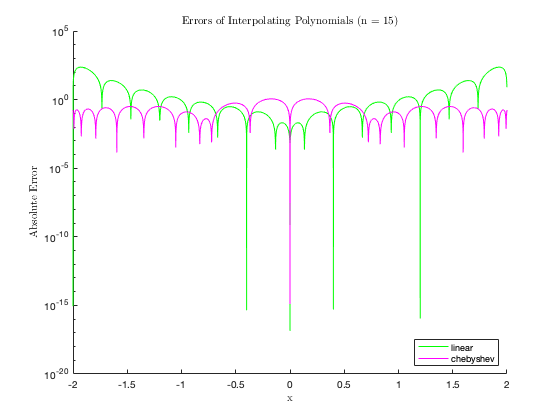

max linear error: 231.34063


max chebyshev error: 1.13225

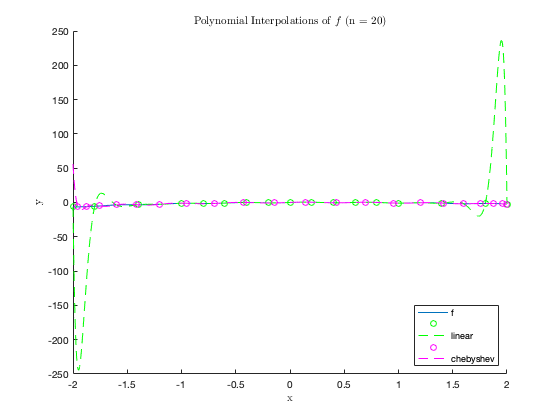

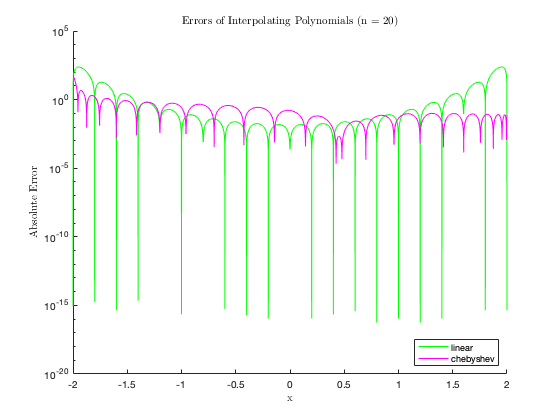

max linear error: 238.18072


max chebyshev error: 62.48382

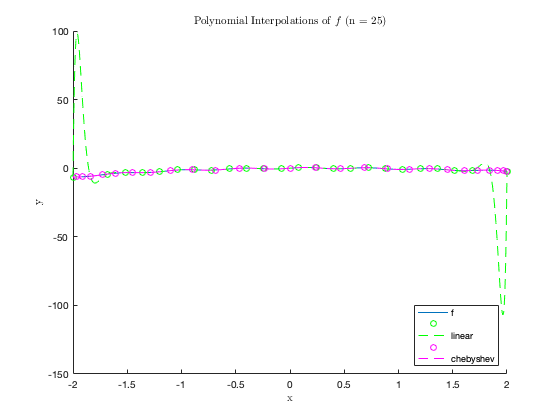

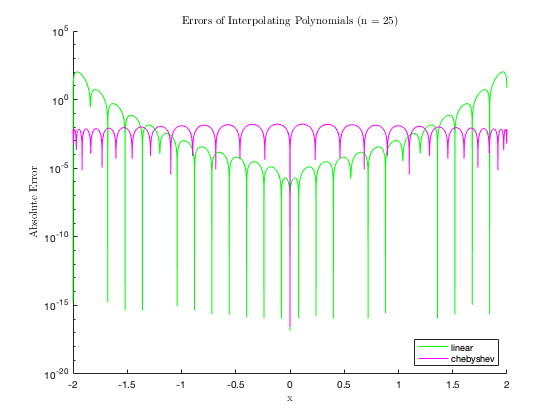

max linear error: 104.96207


max chebyshev error: 0.01615

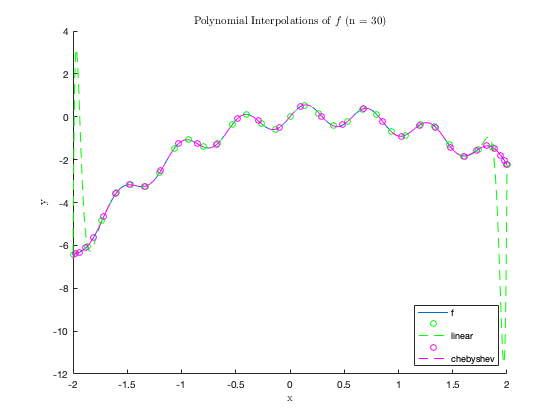

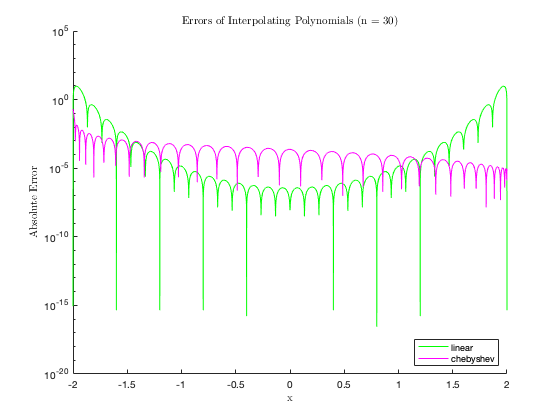

max linear error: 9.49873


max chebyshev error: 0.19624

for n = 5:5:30 % order of polynomial
    % Linear -- interpolating points
    xl = linspace(a, b, n+1);
    yl = f(xl);

    % Linear -- plotting points
    yyl = arrayfun(@(xi) neville(xl, yl, n+1, xi), xx);

    % Chebyshev -- interpolating points
    xc = chebyshev_points(a, b, n+1);
    yc = f(xc);

    % Chebyshev -- plotting points
    yyc = arrayfun(@(xi) neville(xc, yc, n+1, xi), xx);

    % Plot interpolations
    figure

    hold on
    fplot(f, [a, b]);
    plot(xl, yl, 'go', xx, yyl, 'g--');
    plot(xc, yc, 'mo', xx, yyc, 'm--');
    hold off
    
    legend('f', '', 'linear', '', 'chebyshev', 'Location', 'southeast');

    t = sprintf('Polynomial Interpolations of $f$ (n = %d)', n);
    title(t, 'interpreter', 'latex');

    xlabel('x', 'interpreter', 'latex');
    ylabel('y', 'interpreter', 'latex');
    
    % saveas(gcf, sprintf('q1-%d-interp.png', n));
    
    % Plot errors
    figure

    hold on
    plot(xx, abs(yy - yyl), 'g');
    plot(xx, abs(yy - yyc), 'm');
    hold off

    legend('linear', 'chebyshev', 'Location', 'southeast');

    t = sprintf('Errors of Interpolating Polynomials (n = %d)', n);
    title(t, 'interpreter', 'latex');

    xlabel('x', 'interpreter', 'latex');
    ylabel('Absolute Error', 'interpreter', 'latex');
    
    set(gca, 'YScale', 'log')
    
    % saveas(gcf, sprintf('q1-%d-err.png', n));
    fprintf('max linear error: %0.5f\n', max(abs(yy-yyl)));
    fprintf('max chebyshev error: %0.5f', max(abs(yy-yyc)));
end

## 2

data = readmatrix('lab3_data.txt')

data =          0    2.9000    3.5000
    1.0000    2.6000    4.0500
    2.0000    2.0000    4.2000
    3.0000    1.5000    3.9000
    4.0000    1.2000    3.4000
    5.0000    1.3000    2.8000
    6.0000    1.8000    2.4000
    7.0000    2.5000    2.2500
    8.0000    2.9000    1.7000
    9.0000    2.9000    0.9000


------ ds = 1, n = 13 ------


min x: -1.04884, max x: 4.48896


min y: 0.42885, max y: 5.02324

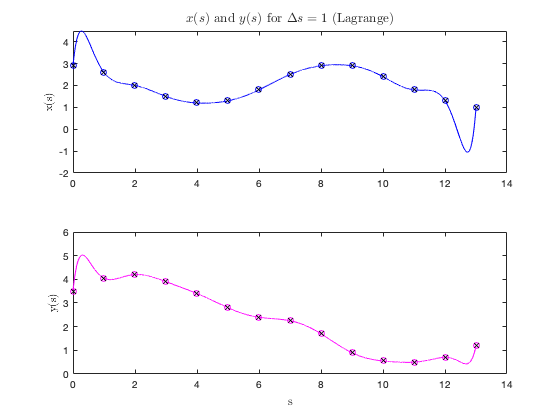

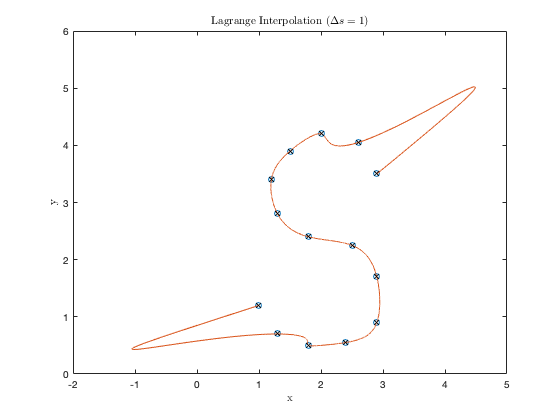

------ ds = 2, n = 6 ------


min x: 1.19263, max x: 2.98710


min y: 0.05646, max y: 4.20808

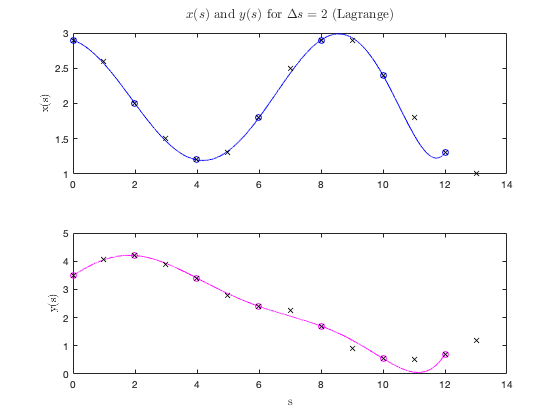

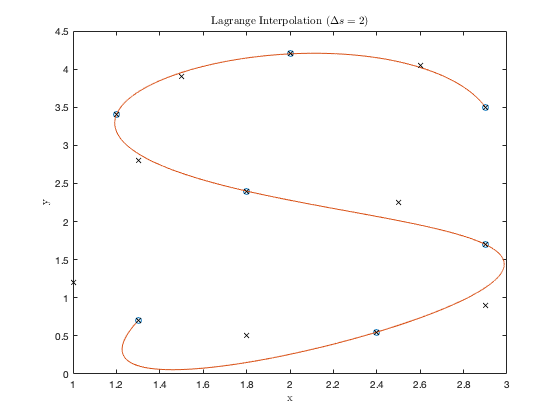

------ ds = 3, n = 4 ------


min x: 1.30000, max x: 2.95407


min y: 0.56513, max y: 4.09457

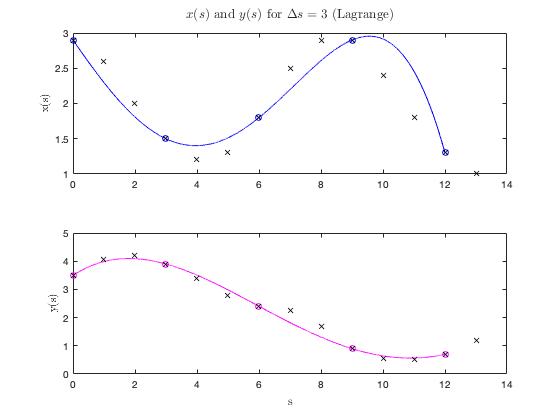

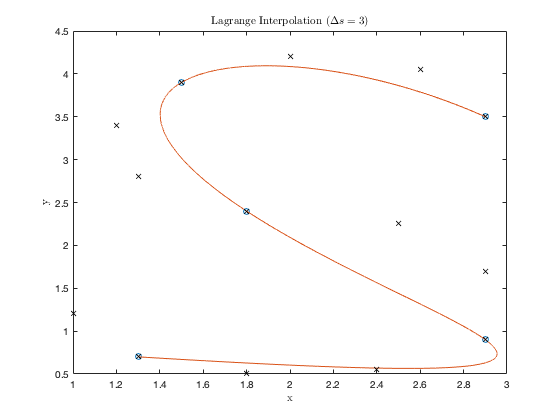

------ ds = 4, n = 3 ------


min x: 1.04421, max x: 3.07283


min y: 0.69771, max y: 3.80059

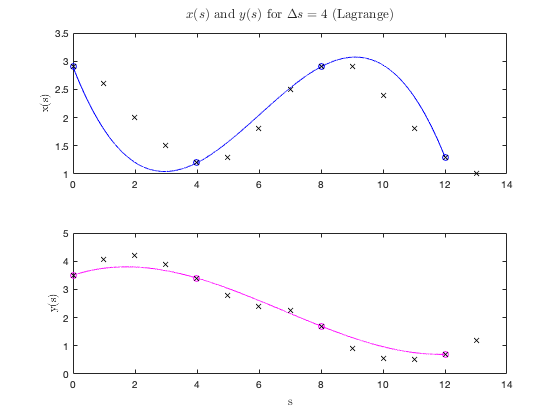

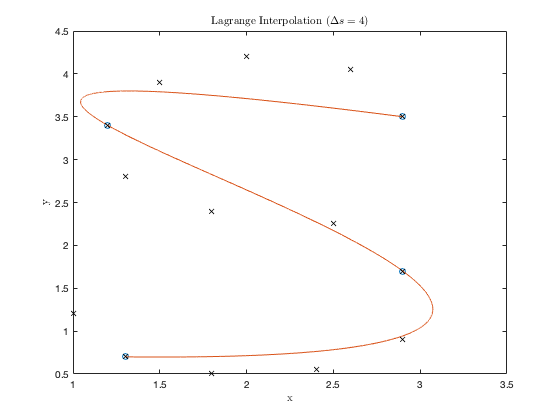

------ ds = 5, n = 2 ------


min x: 1.28843, max x: 2.90000


min y: 0.55000, max y: 3.50181

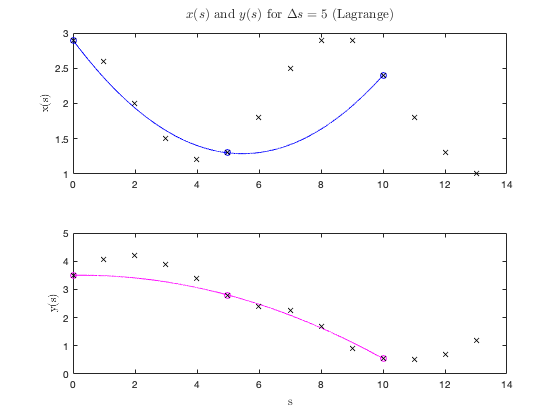

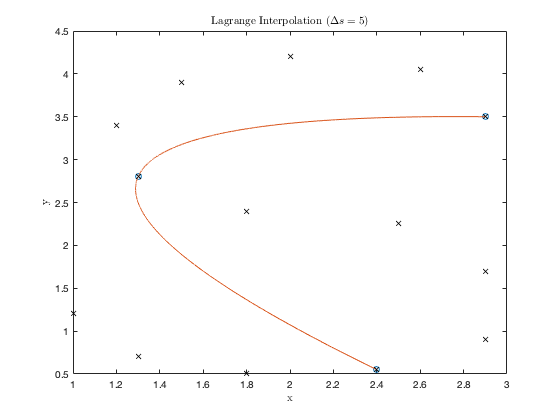

------ ds = 6, n = 2 ------


min x: 1.30000, max x: 2.90000


min y: 0.70000, max y: 3.50000

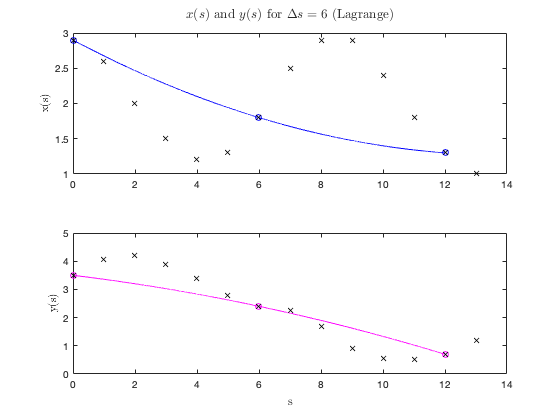

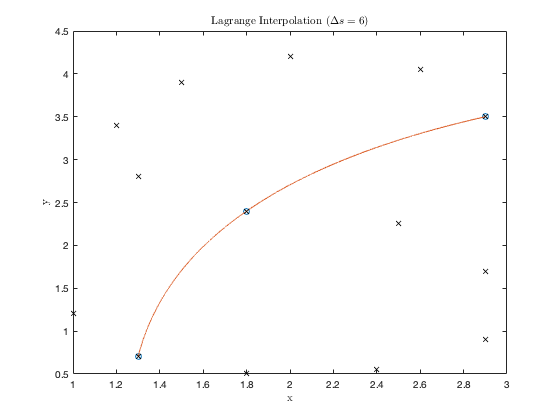


sdata = data(:, 1);
xdata = data(:, 2);
ydata = data(:, 3);

for ds = 1 : 6
    s = sdata(1:ds:end);
    x = xdata(1:ds:end);
    y = ydata(1:ds:end);
    
    a = min(s);     % left bound of interval
    b = max(s);     % right bound of interval
    h = 0.001;      % step size for plotting

    ss = a:h:b;
    
    xx = arrayfun(@(si) neville(s, x, length(s), si), ss);
    yy = arrayfun(@(si) neville(s, y, length(s), si), ss);

    fprintf('------ ds = %d, n = %d ------\n', ds, length(s) - 1);
    fprintf('min x: %0.5f, max x: %0.5f\n', min(xx), max(xx));
    fprintf('min y: %0.5f, max y: %0.5f', min(yy), max(yy));
    
    figure
    t = tiledlayout(2, 1);

    % Plot x(s)
    nexttile
    plot(s, x, 'bo', ss, xx, 'b-', sdata, xdata, 'kx')
    ylabel('x(s)', 'Interpreter', 'latex')

    % Plot y(s)
    nexttile
    plot(s, y, 'mo', ss, yy, 'm-', sdata, ydata, 'kx')
    ylabel('y(s)', 'Interpreter', 'latex')

    % Label
    title(t, sprintf('$x(s)$ and $y(s)$ for $\\Delta s = %d$ (Lagrange)', ds), 'Interpreter', 'latex');
    xlabel(t, 's', 'Interpreter', 'latex')
    
    % saveas(gcf, sprintf('q2-ds%d-sxsy.png', ds));
    
    % Plot interpolated shape
    figure
    plot(x, y, 'o', xx, yy, '-', xdata, ydata, 'kx')
    
    xlabel('x', 'Interpreter', 'latex')
    ylabel('y', 'Interpreter', 'latex')
    title(sprintf('Lagrange Interpolation ($\\Delta s = %d$)', ds), 'Interpreter', 'latex');
    
    % saveas(gcf, sprintf('q2-ds%d-xy.png', ds));
end

## 3


data = readmatrix('lab3_data.txt');

s = data(:, 1);
x = data(:, 2);
y = data(:, 3);

a = min(s);     % left bound of interval
b = max(s);     % right bound of interval
n = length(s);  % number of points
m = 1000;       % how many points to plot per segment

[~, xx] = evaluate_spline(n, s, x, m, 'q3-ds1-x');
[ss, yy] = evaluate_spline(n, s, y, m, 'q3-ds1-y');

fprintf('------ ds = 1 ------\n');

------ ds = 1 ------


fprintf('min x: %0.5f, max x: %0.5f\n', min(min(xx)), max(max(xx)));

min x: 1.00000, max x: 2.96208


fprintf('min y: %0.5f, max y: %0.5f\n', min(min(yy)), max(max(yy)));

min y: 0.49191, max y: 4.21027


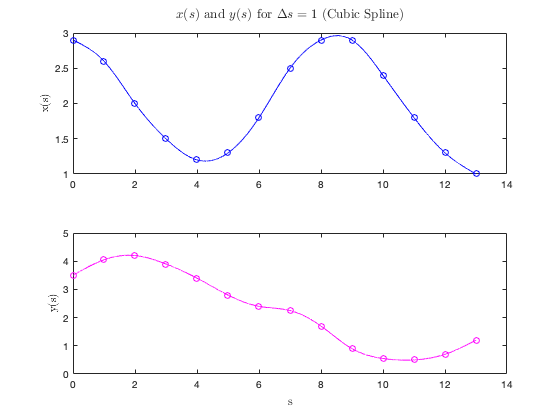


figure
t = tiledlayout(2, 1);

% Plot x(s)
nexttile
plot(ss, xx, 'b-', s, x, 'bo')
ylabel('x(s)', 'Interpreter', 'latex')

% Plot y(s)
nexttile
plot(ss, yy, 'm-', s, y, 'mo')
ylabel('y(s)', 'Interpreter', 'latex')

title(t, '$x(s)$ and $y(s)$ for $\Delta s = 1$ (Cubic Spline)', 'Interpreter', 'latex');
xlabel(t, 's', 'Interpreter', 'latex')

saveas(gcf, 'q3-ds1-sxsy.png');

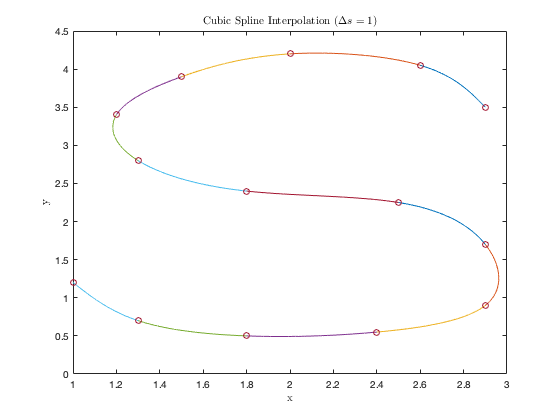


% Plot interpolated shape
figure
plot(xx, yy, '-', x, y, 'o')
   
xlabel('x', 'Interpreter', 'latex')
ylabel('y', 'Interpreter', 'latex')
title('Cubic Spline Interpolation ($\Delta s = 1$)', 'Interpreter', 'latex');

saveas(gcf, 'q3-ds1-xy.png');

## Functions

function p = chebyshev_points(a, b, n)
    %{
        Returns 
        
        Parameters:
            a: left bound of interval
            b: right bound of interval
            n: number of points
    %}
    
    p = zeros(1, n);
    
    for i = 0 : n-1
        xi = cos((2*i + 1) * pi / (2 * (n+1)));
        p(i+1) = (a+b)/2 + (b-a)/2 * xi;
    end
end

function yi = neville(x, y, n, xi)
    %{
        Neville's method. 
        
        Parameters:
            x: x values
            y: y values, f(x)
            n: number of points (order n-1)
            xi: point to evaluate
        
        Returns:
            yi: interpolated y value of xi  
    %}
    
    p = zeros(n, n);

    p(1, :) = y; % first row

    for i = 2 : n
        for j = i : n
            p(i, j) = ((xi - x(j-i+1)) * p(i-1, j) - ... 
                       (xi - x(j)) * p(i-1, j-1)) ...
                        / (x(j) - x(j-i+1));
        end
    end
    
    yi = p(end, end);
end

function [a, b, c, d] = cubic_spline(n, x, a)
    %{
        Natural cubic spline. 
        Based on Algorithm 3.4 in the textbook.
        
        Parameters:
            n: number of points
            x: x values
            a: y values
        
        Returns:
            [a, b, c, d]: four (n-1)x1 arrays of polynomial coefficients:
                a + b(x - xi) + c(x - xi)^2 + d(x - xi)^3
    %}
    
    m = n - 1;    % number of segments
    
    h = zeros(m, 1);
    for i = 1 : m
        h(i) = x(i+1) - x(i);
    end
    
    p = zeros(m, 1);
    for i = 2 : m
        p(i) = 3/h(i) * (a(i+1) - a(i)) - 3/h(i-1) * (a(i) - a(i-1));
    end
    
    l = zeros(n, 1);
    u = zeros(n, 1);
    z = zeros(n, 1);
    
    l(1) = 1;
    l(n) = 1;
    
    for i = 2 : m
        l(i) = 2 * (x(i+1) - x(i-1)) - h(i-1) * u(i-1);
        u(i) = h(i) / l(i);
        z(i) = (p(i) - h(i-1) * z(i-1)) / l(i);
    end
    
    b = zeros(n, 1);
    c = zeros(n, 1);
    d = zeros(n, 1);
    
    for j = m : -1 : 1
        c(j) = z(j) - u(j)*c(j+1);
        b(j) = (a(j+1) - a(j)) / h(j) - h(j) * (c(j+1) + 2*c(j)) / 3;
        d(j) = (c(j+1) - c(j)) / (3 * h(j));
    end
    
     a = a(1:end-1);
     b = b(1:end-1);
     c = c(1:end-1);
     d = d(1:end-1);
end

function [xx, yy] = evaluate_spline(n, x, y, m, fileprefix)
    %{
        Returns plotting points for a cubic spline 
        given a set of x and y values. 

        Parameters:
            n: number of points
            x: x values
            y: y values
            m: # points to plot per segment
            fileprefix: prefix for output file
    %}
    
    % Get coefficients for each segment 
    [a, b, c, d] = cubic_spline(n, x, y);
    writematrix([a b c d], sprintf('%s-coefs.csv', fileprefix));
    
    % Store plotting points in xx and yy
    xx = zeros(m, n-1);
    yy = zeros(m, n-1);
    
    % Get plotting points for each segment
    for i = 1 : n-1
        
        % Cubic interpolation for this segment
        p = @(xp) a(i) + b(i).*(xp - x(i)) + c(i).*(xp - x(i)).^2 + d(i).*(xp - x(i)).^3;
        
        xx(:, i) = linspace(x(i), x(i+1), m);
        yy(:, i) = p(xx(:, i)); 
    end  
end